# Adds CV pipe and junction in a network with the bin Function addBinJunction.

This example contains: 

- Load a network. 

- Plot newtork with bin functions. 

- Add Junction + CV pipe. 

- Plot normal with new pipe. 

- Unload library.

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


##  Load a network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



disp('Add CV PIPE with Bin Functions addBinJunction')

Add CV PIPE with Bin Functions addBinJunction


##  Plot network with bin functions.

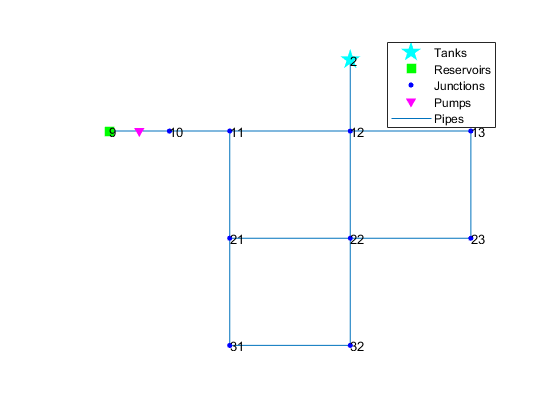

d.Binplot('nodes','yes');
%  addBinJunction
%  arguments: newNodeID,X,Y,ToNodeID,newElevation,newBaseDemand,newDemandPattern,newPipeID,
%  newLength,newDiameter,newRoughness,Code
%  Add Junction + CV pipe.
newID='J1';
[x,y]=ginput(1);

ToNodeID='10'; 
newElevation=500; % ft
newBaseDemand=0;
newDemandPattern='1';
newPipeID='CV-P2';
newLength=1000; % ft
newDiameter=10; % in
newRoughness=100;
patternCategoryID = '';
quality = 0.5;

Code='CVPIPE';'CVPIPE', 'PIPE', 'PUMP', 'PRV', 'PSV', 'PBV', 'FCV', 'TCV', 'GPV'

ans = 'CVPIPE'

ans = 'PIPE'

ans = 'PUMP'

ans = 'PRV'

ans = 'PSV'

ans = 'PBV'

ans = 'FCV'

ans = 'TCV'

ans = 'GPV'


[node_index, link_index] = d.addBinNodeJunction(newID, [x, y], newElevation, newBaseDemand, newDemandPattern, patternCategoryID, quality,...
      {'PIPE', {newPipeID}, newID, ToNodeID, newLength, newDiameter, newRoughness}); 

##  Plot normal with new pipe.

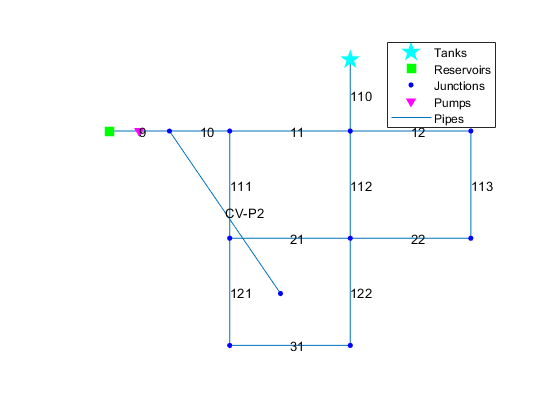

d.plot('links','yes');

##  Unload library.

d.unload

EPANET Class is unloaded
